# Cálculos Iniciales

- Definición de tau:

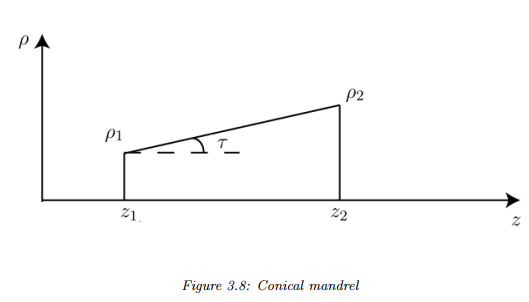

- Definición de espesor de la cinta: El espesor de la fibra se calcula como:

$\textrm{esp}=\frac{\textrm{TEX}}{1000*\textrm{RW}*\textrm{fibdens}}$=0.4520=800/(1000*1*1.77)

- Definición de ancho efectivo (Sotiris Koussios. "Filament Winding: A Unified Approach". 2004.):

function vector_salida_calculos_iniciales = calculos_iniciales(var_ini, excel)
    %Definicion de variables de entrada:
    alfainicio = var_ini.alfainicio; % alfainicio: ángulo de bobinado en la coordenada inicial de bobinado (zi) en grados α  [-90; 90].
    b = var_ini.b; % b: ancho de hilo de fibra en mm.
    fibdens = var_ini.fibdens; % fibdens: densidad de la fibra en g=cm3.
    fmc = var_ini.fmc; % fmc: contenido en masa de fibra.
    resdens = var_ini.resdens; % resdens: densidad de la resina en g=cm3.
    rfm = var_ini.rfm; % rfm: Radio del mandril en el extremo derecho en mm.
    rim = var_ini.rim; % rim: Radio del mandril en el extremo izquierdo en mm.
    RW = var_ini.RW; % RW: b/NR - ancho de mecha en mm.
    TEX = var_ini.TEX; % TEX: valor TEX en g/km.
    zfg = var_ini.zfg; % zfg: Coordenada del extremo geodésico derecho del mandril en mm.
    zfm = var_ini.zfm; % zfm: Coordenada del extremo derecho del mandril en mm.
    zi = var_ini.zi; % zi: Coordenada del inicio del devanado en mm.
    zig = var_ini.zig; % zig: Coordenada del extremo geodésico izquierdo del mandril en mm.
    zim = var_ini.zim; % zim: Coordenada del extremo izquierdo del mandril en mm.
    
    %Inicializamos las variables de salida de la funcion
    vector_salida_calculos_iniciales = struct();
    celda_salida_calculos_iniciales = {};

    %% Cálculos iniciales
    alfai = alfainicio * pi / 180; %alfa en radianes.
    lm = zfm - zim; % Longitud del bobinado.
    lg = zfg - zig; % Longitud zona geodésica.
    dm = rfm - rim; % Diferencia entre radios del mandril. Si dm=0, el mandril es cilindrico.
    rig = ((zig * dm / lm) + rim - (dm * zim / lm)); % radio de inicio de la zona geodésica.
    ri = ((zi * dm / lm) + rim - (dm * zim / lm)); % radio de la secccion de inicio del bobinado.
    rfg = ((zfg * dm / lm) + rim - (dm * zim / lm)); %radio final de la zona geodésica.
    tau = atan(dm / lm); % Ángulo importante si la superficie es cónica. Véase la Figura 3.8.
    zeroteta = (zfg + zig) / 2; % Centro del eje de coordenadas esféricas.
    rc = rim; % radio menor del cono, que siempre es el izquierdo.

    if rig == rfg %Condición cilindro.
        beff = b / cos(alfai); % Ancho efectivo.
        nreal = 2 * pi * rc / beff;
        n1 = ceil(nreal); %cuantas pasadas como número entero debo hacerle al mandril para cubrirlo.
        vector_salida_calculos_iniciales.beff = beff;
        vector_salida_calculos_iniciales.nreal = nreal;
        vector_salida_calculos_iniciales.n1 = n1;
        celda_salida_calculos_iniciales(2, :) = {'beff', vector_salida_calculos_iniciales.beff};
        celda_salida_calculos_iniciales(9, :) = {'nreal', vector_salida_calculos_iniciales.nreal};
        celda_salida_calculos_iniciales(8, :) = {'n1', vector_salida_calculos_iniciales.n1};
    end

    % Espesor
    fd = fmc * fibdens + (1 - fmc) * resdens;
    esp = TEX / (1000 * RW * fibdens);

    %Vector de variables de salida
    vector_salida_calculos_iniciales.alfai = alfai;
    vector_salida_calculos_iniciales.dm = dm;
    vector_salida_calculos_iniciales.esp = esp;
    vector_salida_calculos_iniciales.fd = fd;
    vector_salida_calculos_iniciales.lg = lg;
    vector_salida_calculos_iniciales.lm = lm;
    vector_salida_calculos_iniciales.rc = rc;
    vector_salida_calculos_iniciales.rfg = rfg;
    vector_salida_calculos_iniciales.ri = ri;
    vector_salida_calculos_iniciales.rig = rig;
    vector_salida_calculos_iniciales.tau = tau;
    vector_salida_calculos_iniciales.zeroteta = zeroteta;
    % Escribir una celda, ya que es más fácil exportar un archivo con formato de celdas
    celda_salida_calculos_iniciales(1, :) = {'alfai', vector_salida_calculos_iniciales.alfai};
    celda_salida_calculos_iniciales(3, :) = {'dm', vector_salida_calculos_iniciales.dm};
    celda_salida_calculos_iniciales(4, :) = {'esp', vector_salida_calculos_iniciales.esp};
    celda_salida_calculos_iniciales(5, :) = {'fd', vector_salida_calculos_iniciales.fd};
    celda_salida_calculos_iniciales(6, :) = {'lg', vector_salida_calculos_iniciales.lg};
    celda_salida_calculos_iniciales(7, :) = {'lm', vector_salida_calculos_iniciales.lm};
    celda_salida_calculos_iniciales(10, :) = {'rc', vector_salida_calculos_iniciales.rc};
    celda_salida_calculos_iniciales(11, :) = {'rfg', vector_salida_calculos_iniciales.rfg};
    celda_salida_calculos_iniciales(12, :) = {'ri', vector_salida_calculos_iniciales.ri};
    celda_salida_calculos_iniciales(13, :) = {'rig', vector_salida_calculos_iniciales.rig};
    celda_salida_calculos_iniciales(14, :) = {'tau', vector_salida_calculos_iniciales.tau};
    celda_salida_calculos_iniciales(15, :) = {'zeroteta', vector_salida_calculos_iniciales.zeroteta};
    % Escribir un archivo con las variables de entrada
    writecell(celda_salida_calculos_iniciales, excel, 'Sheet', 'Cálculos iniciales', 'Range', 'A1');
end